# 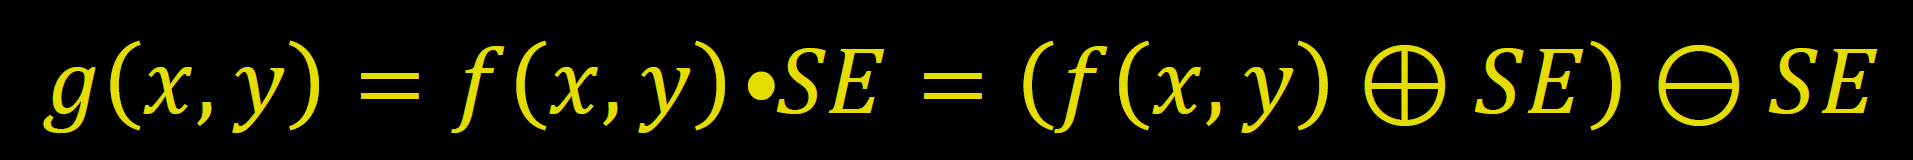

# 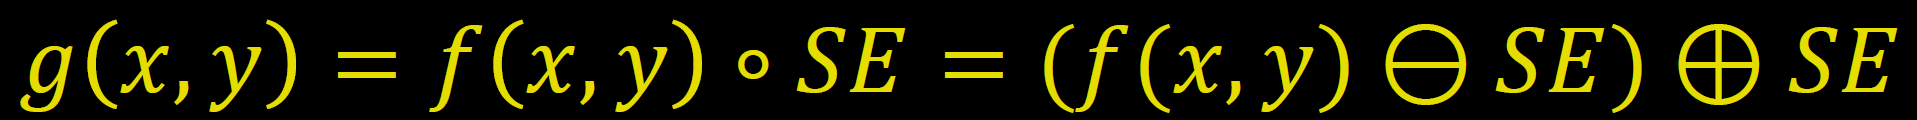

# max rank filter


clc
clear all
A=[203 167 233 113 222 232;
    79 176 39 27 22 46; 
    135 191 211 245 102 67;
    42 115 137 1 66 37;
    154 21 254 198 204 35
    67 58 20 208 110 222];

B = ordfilt2(A,9,ones(3,3));

threshold = 250; % custom threshold value
B = B > threshold;

%TP/FP+TP

7/(2+7)

ans = 0.7778


%% bound

## true positive || false negativee || accuracy

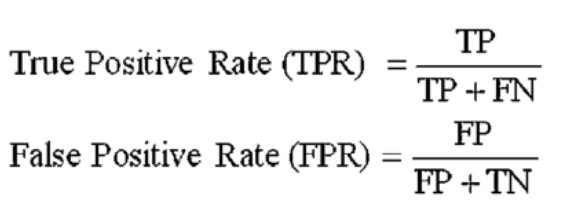

TP = 8;         % True poseitive, elementer markede som posetive og de er også posetive dedekteret
FN = 4;         % false negative, ting som burde være dedekteret positive men som er negative / ikke dedekteret

TPR = round(TP / (TP + FN),2)

TPR = 0.6700

## homography

clc; clear all; close all;
x=10;
y=30;
point=[x,y]

point =     10    30


d=transpose([3,1,4,2,7,6,2,1])

d =      3
     1
     4
     2
     7
     6
     2
     1


## normalize

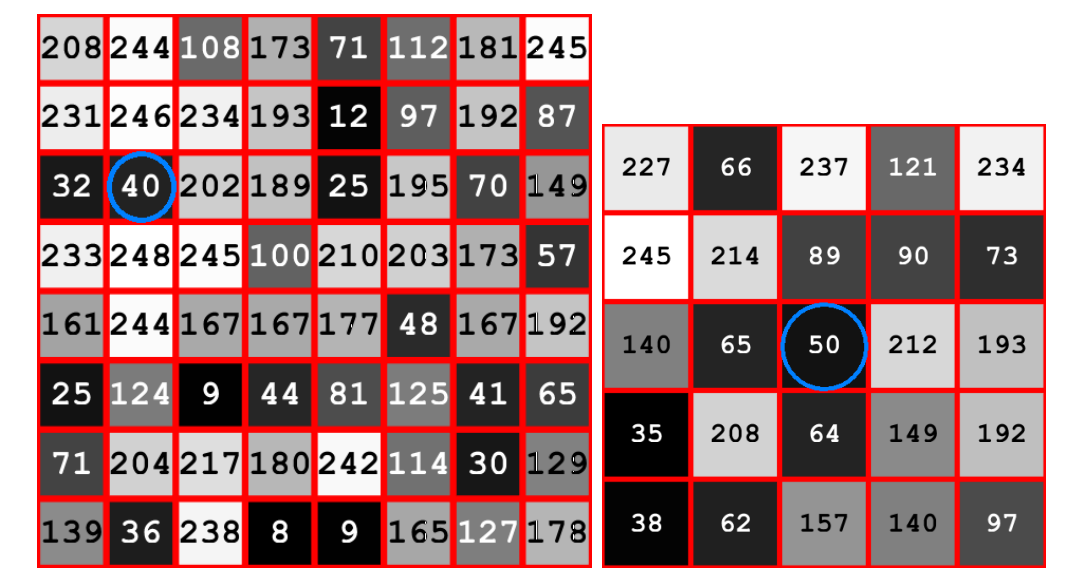

clc; clear all; close all;

map =   [208 244 108 173 71 112 181 245;
        231 246 234 193 12 97 192 87;
        32 40 202 189 25 195 70 149;
        233 248 245 100 210 203 173 57;
        161 244 167 167 177 48 167 192;
        25 124 9 44 81 125 41 65;
        71 204 217 180 242 114 30 129;
        139 36 238 8 9 165 127 178];

kernel=[227 66 237 121 234;
        245 214 89 90 73;
        140 65 50 212 193;
        35 208 64 149 192;
        38 62 157 140 97;];

normalisation_factor=sum(kernel,'all');
normalized_kernal=kernel/normalisation_factor;

svar=round(imfilter(map,normalized_kernal));

% vi vil gerne have svaret fra position 3,2

svar(3,2)

ans = 154

## minimum filter | linear mapping 

clc; clear all; close all;
map=[202,238,167,12,242;
    245,173,44,25,9;
    167,193,180,210,112;
    9,189,8,177,97;
    217,100,71,81,195];

old_max = max(map,[],'all');      % tag max værdi som er i matricen lige nu
old_min = min(map,[],'all');;     % tag min værdi som er i matricen lige nu

new_max = 150;                    % ny min / max værdier. 
new_min = 50;

%linear mapping 
new_map=round((map - old_max)*(new_min-new_max)/(old_min-old_max) + new_max)

new_map =    132   147   117    52   149
   150   120    65    57    50
   117   128   123   135    94
    50   126    50   121    88
   138    89    77    81   129


B = round(ordfilt2(new_map,1,ones(3,3)))

B =      0     0     0     0     0
     0    65    52    50     0
     0    50    50    50     0
     0    50    50    50     0
     0     0     0     0     0


## median filter | max filter

clc; clear all; close all;
map=[202,238,167,12,242;
    245,173,44,25,9;
    167,193,180,210,112;
    9,189,8,177,97;
    217,100,71,81,195];

% '9' indcates a maximum rank filter 
temp_map = ordfilt2(map,9,ones(3,3))

temp_map =    245   245   238   242   242
   245   245   238   242   242
   245   245   210   210   210
   217   217   210   210   210
   217   217   189   195   195


% the argument '5' indicates this is a median filter, more information can
% be found in the ordfilt2 help documentation
answer=round(ordfilt2(temp_map,5,ones(3,3)));


## Normalised Cross Correlation

g = [149,19,3;
    140,14,86;
    234,135,41]

g =    149    19     3
   140    14    86
   234   135    41


h = [66,232,37;
    204,46,35;
    110,67,222]

h =     66   232    37
   204    46    35
   110    67   222



length_template=sqrt(sum(sum(h.*h)))

length_template = 412.7699

lenght_image=sqrt(sum(sum(g.*g)))

lenght_image = 352.7393

corr=(sum(sum(g.*h)))

corr = 90454



Normalised_corralation=corr/(lenght_image*length_template)

Normalised_corralation = 0.6212

## cross corralation || grayscale

image = [208,139,204,9,167,210,195;
            231,244,36,217,44,177,203;
            32,246,108,238,180,81,48;
            233,40,234,173,8,242,125;
            161,248,202,193,71,9,114;
            25,244,245,189,12,112,165;
            71,124,167,100,25,97,181];
        
image_3x3=[238,180,81;
              173,8,242;
              193,71,9]

image_3x3 =    238   180    81
   173     8   242
   193    71     9


          
% used to convert from RGB to grayscale
W_r=0.299;
W_g=0.587;
W_b=0.114;
        
rgb1=[120,40,20];
rgb2=[20,150,60];
rgb3=[30,20,150];
rgb4=[170,20,190];
rgb5=[20,110,20];
rgb6=[70,20,250];
rgb7=[120,25,20];
rgb8=[140,20,30];
rgb9=[70,20,40];

%rgb image converted to grayscale with formula from book page 109
template_rgb_to_gray=[W_r*rgb1(1)+W_g*rgb1(2)+W_b*rgb1(3),W_r*rgb2(1)+W_g*rgb2(2)+W_b*rgb2(3),W_r*rgb3(1)+W_g*rgb3(2)+W_b*rgb3(3);
            W_r*rgb4(1)+W_g*rgb4(2)+W_b*rgb4(3),W_r*rgb5(1)+W_g*rgb5(2)+W_b*rgb5(3),W_r*rgb6(1)+W_g*rgb6(2)+W_b*rgb6(3);
            W_r*rgb7(1)+W_g*rgb7(2)+W_b*rgb7(3),W_r*rgb8(1)+W_g*rgb8(2)+W_b*rgb8(3),W_r*rgb9(1)+W_g*rgb9(2)+W_b*rgb9(3)]

template_rgb_to_gray =    61.6400  100.8700   37.8100
   84.2300   72.8300   61.1700
   52.8350   57.0200   37.2300


%finding corralation
corr=(sum(sum(image_3x3.*template_rgb_to_gray)))

corr = 8.0428e+04

## covariance matrix

% spørgsmål 1 eksamensæt 2020
% kan findes mere om det i PDF side 79
% men ligningen cov_matrix=(1/n)*X_1*transpose(X_1)
% hvor n er antallet af rows. 

clc;clear all; close all;
syms V
n=3;

muligheder=[17,4,13,6,7];

svar=[249,-50,-96;-50,13,26;-96,26,53];

for V=muligheder
    X_1=[4,V,-21;-3,-2,5;-7,-3,10];
    if round((1/3)*X_1*X_1') == svar
        disp('svar: ')
        disp(V)
    end 
end

svar: 


    17



TP = 9

TN = 13

N = 31

accuracy = 0.7097

## CCD chip

% 2020 eksamensæt Find højde af billede på chip
% bruger ligningen B=b*(G/g)
% b og G er givet

b=2.3*10^-3;
G=50*10^-2;

% B kan udregnes da højden er givet i pixel, samt specificationer omkring
% sensoren og billedets størrelse. 

sensor_physical_height=6.5*10^-3;
image_pixel_height=7800;

physical_height_of_1_pixel=sensor_physical_height/image_pixel_height;
physical_height_of_400_pixels=400*physical_height_of_1_pixel;

B=physical_height_of_400_pixels;
syms g
eval(solve(B==b*(G/g),g))

ans = 3.4500

## more CCD

% how many pixel wil an object be in the photo
clc; clear all; close all;

G=1.2;
g=7;
b=1.5*10^-3;

% bruger ligning B=b*(G/g) for at isolere B, dette giver den fysiske højde
% af billede på sensoren, hefter kan antallet af pixel findes. 

B=b*(G/g)

B = 2.5714e-04


sensor_width=4.2*10^-3;
sensor_width_procent=(B/sensor_width)*100 % finding procentage of width the object takes up on sensor

sensor_width_procent = 6.1224


pixel_width=5040;

round((pixel_width/100)*sensor_width_procent) % finding the equivilent procentage is of the pixel count

ans = 309

## CCD focal length

## horizontal field

FOV=deg2rad(35);
f=20*10^-3

f = 0.0200

svar=tan(FOV/2)*focal*2

'dist' requires one of the following:
  Deep Learning Toolbox
  Navigation Toolbox
  Robotics System Toolbox
  Sensor Fusion and Tracking Toolbox

## RGB || HSI

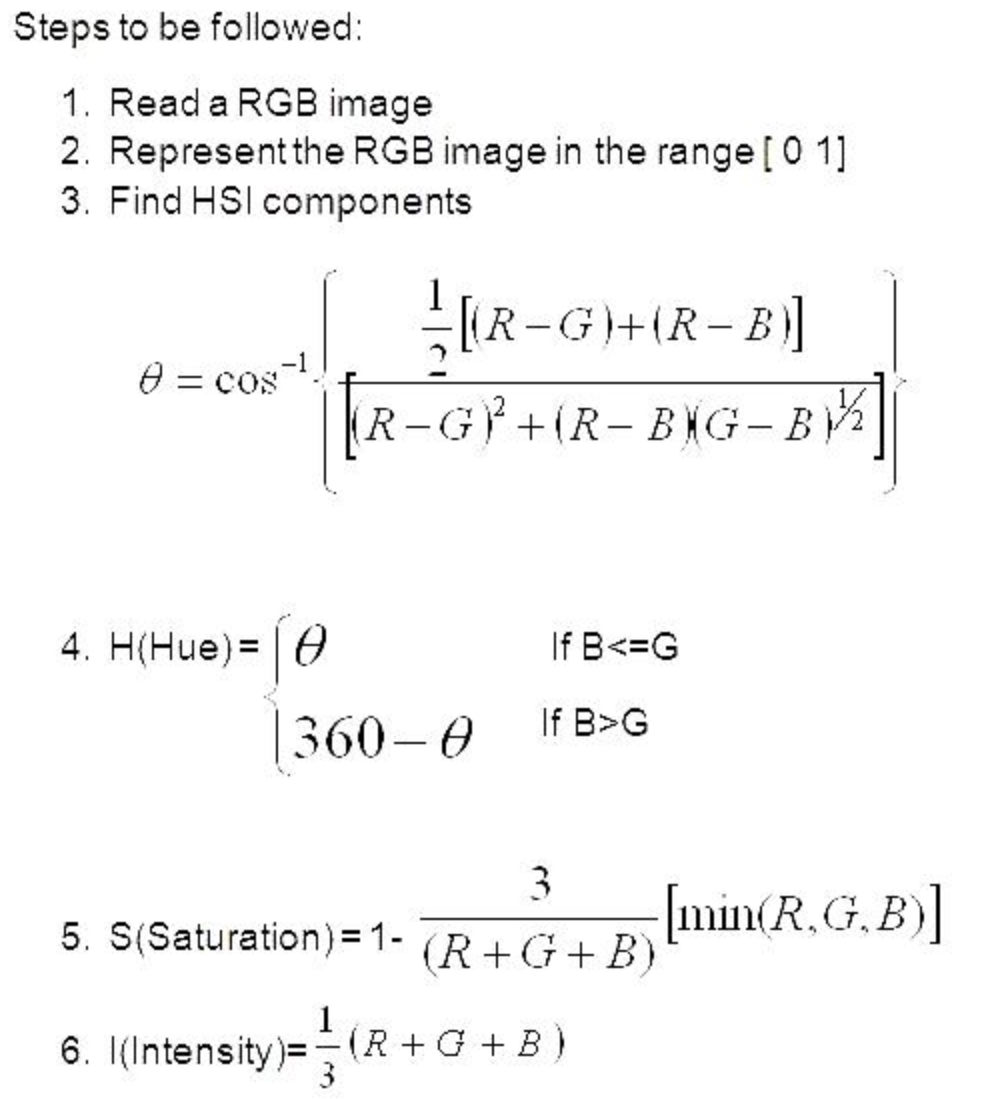

clc; clear all; close all;

A =    24.3333   56.6667   90.0000
   70.0000  126.6667  110.0000
   53.3333   60.0000   25.0000


ans = 3×3 uint8 matrix
    20    71   123
    91   180   154
    65    76    21


rgb1 = [18 10 45];
rgb2 = [25 75 70];
rgb3 = [25 90 155];
rgb4 = [ 170 30 10];
rgb5 = [10 150 220];
rgb6 = [250 10 70];
rgb7 = [140 20 0];
rgb8 = [0 20 160];
rgb9 = [10 20 45];

% array converts from RGB to HSI by summing and dividing by 3. 
A= [sum(rgb1)/3 sum(rgb2)/3 sum(rgb3)/3;
    sum(rgb4)/3 sum(rgb5)/3 sum(rgb6)/3;
    sum(rgb7)/3 sum(rgb8)/3 sum(rgb9)/3];

% finding S  
%A= round([1-(3/(rgb1(1)+rgb1(2)+rgb1(3)))*min([rgb1(1),rgb1(2),rgb1(3)]) 1-(3/(rgb2(1)+rgb2(2)+rgb2(3)))*min([rgb2(1),rgb2(2),rgb2(3)]) 1-(3/(rgb3(1)+rgb3(2)+rgb3(3)))*min([rgb3(1),rgb3(2),rgb3(3)])],2)


graylevelmapping(A,180,20)


## logarithmic mapping

clc; clear all; close all;
max_value_in_map = 242;
map = [193,180,98,112,125;
        189,8,177,97,114;
        100,71,81,195,165;
        167,12,242,203,181;
        44,25,9,48,192];

c=255/(log(1+max_value_in_map));

new_map=round(c*log(1+map))

new_map =    245   241   213   219   225
   244   102   241   213   220
   214   199   205   245   237
   238   119   255   247   242
   177   151   107   181   244


## color tresholding || more HSI

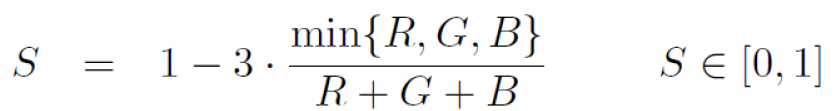

clc; clear all ; close all;
point1=[60 120 210];
point2=[70 125 214];

s1=1-3*((min(point1)/(point1(1)+point1(2)+point1(3))))

s1 = 0.5385

s2=1-3*((min(point2)/(point2(1)+point2(2)+point2(3))))

s2 = 0.4866


s1+s2

ans = 1.0250

## prewitt

clc; clear all; close all; 

svar_mulighed=[98,132,245,151,24]

svar_mulighed =     98   132   245   151    24



for i=svar_mulighed
% Convert the image to double
input_image = [87,129,35;
                149,178,38;
                57,i,66];
  
% Prewitt Operator Mask
Ver_prewitt = [-1 0 1; -1 0 1; -1 0 1];
Hoz_prewitt = [-1 -1 -1; 0 0 0; 1 1 1];


gradiant_vertical=sum(input_image.*Ver_prewitt,'all');
gradiant_horizontal=sum(input_image.*Hoz_prewitt,'all');

svar_regnet=round(sqrt(gradiant_vertical^2+gradiant_horizontal^2),1);

if svar_regnet == 155.7
    disp(i)
end
% temp_img=imfilter(input_image,Hoz_prewitt);
% 
% temp_img2=imfilter(temp_img,Ver_prewitt);
% 
% disp(temp_img2)
end

   151



## horizontal and vertical field

FOV_hoz=deg2rad(40);
FOV_ver=deg2rad(25);
dist=1.5;
distance_horizontal=tan(FOV_hoz/2)*dist*2

distance_horizontal = 1.0919

distance_vertical=tan(FOV_ver/2)*dist*2

distance_vertical = 0.6651

## sobel filter

clc;clear all; close all;
gamma=1.16;
% tager alle værdier og mapper dem mellem 0-1. 
A =[1,66,37,218,61,230;
    198,204,35,159,31,241;
    208,110,220,89,47,125;
    222,232,148,131,61,125;
    22,46,140,102,106,86;
    102,67,37,19,13,230];

A_gamma=round(((A/255).^gamma)*255)

A_gamma =      0    53    27   213    49   226
   190   197    25   147    22   239
   201    96   215    75    36   112
   217   229   136   118    49   112
    15    35   127    88    92    72
    88    54    27    13     8   226



vertical_sobel = [-1,0,1;
                  -2,0,2;
                  -1,0,1]

vertical_sobel =     -1     0     1
    -2     0     2
    -1     0     1


% imfilter does the zero padding itself
imfilter(A_gamma,vertical_sobel)

ans =    303  -111   270    41   118  -120
   543  -289    39  -163   234  -129
   618  -218  -203  -448   160  -143
   589   -36  -190  -388     9  -226
   353    82   -46  -176   175  -241
   143   -10   -29   -73   410  -108


## height of CCD

FOV_hoz=deg2rad(35);
FOV_ver=deg2rad(35);
focal=20;
distance_horizontal=tan(FOV_hoz/2)*focal*2

distance_horizontal = 12.6120

distance_vertical=tan(FOV_ver/2)*focal*2

distance_vertical = 12.6120

## run length code |  compactness

run_length_code=[10,10,10,17,17;
                 17,58,60,21,21;
                 21,21,75,75,75;
                 5,5,8,8,8;
                 8,8,8,2,2]

run_length_code =     10    10    10    17    17
    17    58    60    21    21
    21    21    75    75    75
     5     5     8     8     8
     8     8     8     2     2


             
% denne opgave havde også et treshold på alle værdier over 50 skulle sættes
% til 1 dette gør for loop under
for idx = 1:numel(run_length_code)
    if (run_length_code(idx)>50)
        run_length_code(idx)=1;
    else 
        run_length_code(idx)=0;
    end
end
disp(run_length_code)

     0     0     0     0     0
     0     1     1     0     0
     0     0     1     1     1
     0     0     0     0     0
     0     0     0     0     0




% area af blob = 5e

y_min=1;
x_min=1;
x_max=5;
y_max=3;

svar=5/((y_max-y_min)*(x_max-x_min))

svar = 0.6250

## Minimum distance classification | image classification

%% Exercise 18.13 i 2018 sættet
A = [202,205,206,207,208,210];
B = [74,76,78,82];
C = [106,107,108,110];


% i opgaven bliver spurgt om minimum distance til road class, derfor skal
% det altså være gennemsnittet fra A -> C og B->C da C datasættet
% repræsenteere road class.
Int1= round((mean(A)+mean(C))/2)

meanB = 76.3333

meanC = 68.3333

meanE = 33

map =    181   181   176    80    81    82
   180   178    80    74    75    76
   177    80    77    74    66    65
    80    78    76    68    65    16
    80    78    68    67    19    17
    79    79    70    69    18    18


Int2 =round((mean(B)+mean(C))/2)



##  pixel classification 

clc; clear all; close all;

map=[181,181,176,80,81,82;
    180,178,80,74,75,76;
    177,80,77,74,66,65;
    80,78,76,68,65,16;
    80,78,68,67,19,17;
    79,79,70,69,18,18]

A = [176, 178, 183];
B = [81, 76, 72];
C = [67, 68, 70];
D = [15, 25, 18];
E = [25, 42, 32];

%vi finder alle gennemsnitte
meanA=round(mean(A));
meanB=round(mean(B))
meanC=round(mean(C))
meanD=round(mean(D));
meanE=round(mean(E))

%vi finder midt punktet mellem mean C og den mean der er over og under mean
% C
range1=(meanC+meanB)/2
range2=(meanC+meanE)/2

% tjek alle værdier fra map der ligger i range mellem range1 og range2

## parametric classifier

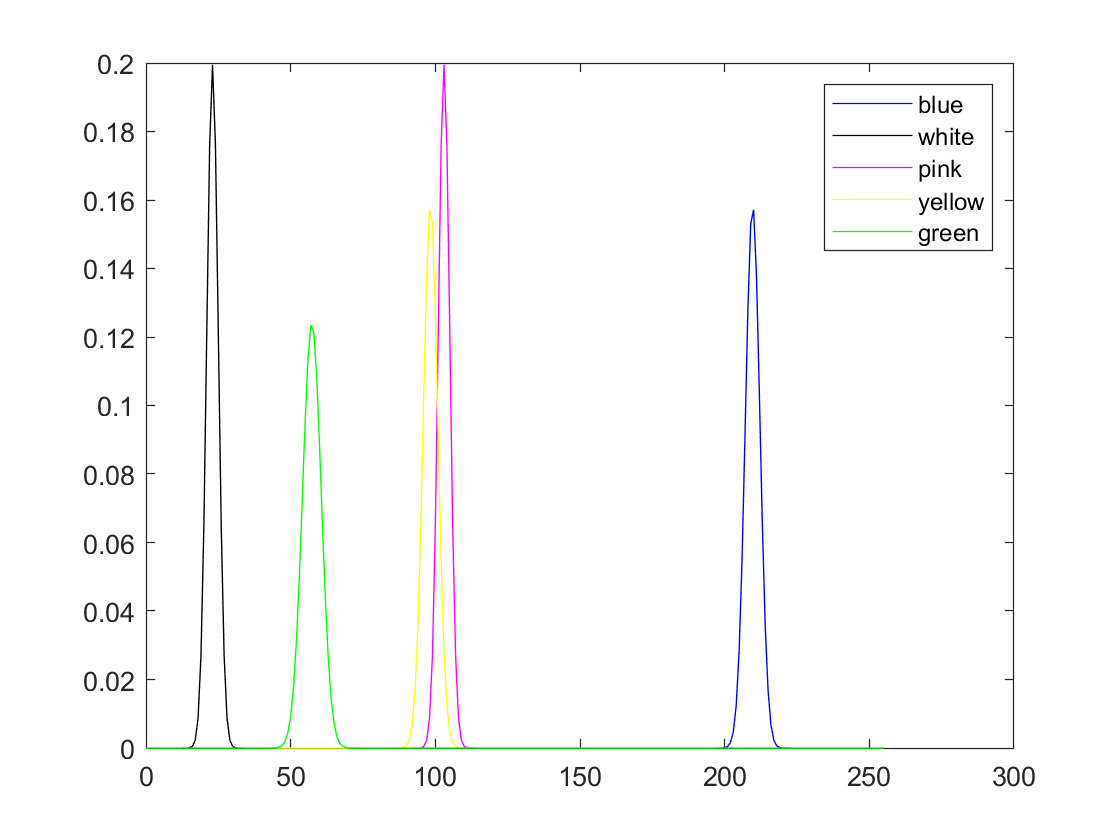

clc; clear all; close all;
% slide 579
% set all regions
car = [210; 212; 207];
road = [23; 25; 21];
sign = [101; 103; 105];
pedestrian = [98; 96; 101];
dog = [55; 56; 61];

plot(0:255,pdf(fitdist(car,'Normal'),0:255),'Color','blue')
hold on
plot(0:255,pdf(fitdist(road,'Normal'),0:255),'Color','black')
plot(0:255,pdf(fitdist(sign,'Normal'),0:255),'Color','magenta')
plot(0:255,pdf(fitdist(pedestrian,'Normal'),0:255),'Color','yellow')
plot(0:255,pdf(fitdist(dog,'Normal'),0:255),'Color','green')
legend('blue','white','pink','yellow','green')


%kig på plot, de 2 overlapper, det plot der har den højeste værdi på Y
%aksen i det punk vi er interreseret i på X aksen r det rigtige svar

## bilinear interpolation

% see example 2019 question 4


theta=deg2rad(8);
point=[33;97];
rotation_matrix = [cos(theta),-sin(theta);sin(theta),cos(theta)]

rotation_matrix =     0.9903   -0.1392
    0.1392    0.9903



point_rot=rotation_matrix*point

point_rot =    19.1791
  100.6487



% from 2020 exercise 2019
%out = (P1(:) + P2(:)).'/2

value=[147,98,197,213];  % values from table 

x = 19;                 % first value from X kordinate in table
y = 100;                % first value from y kordinate in table 

dx = abs(x-point_rot(1))

dx = 0.1791

dy = abs(y-point_rot(2))

dy = 0.6487



svar=(value(1)*(1-dx)*(1-dy))+(value(2)*(dx)*(1-dy))+(value(3)*(1-dx)*(dy))+(value(4)*(dx*dy))

svar = 178.2122

## parametric image

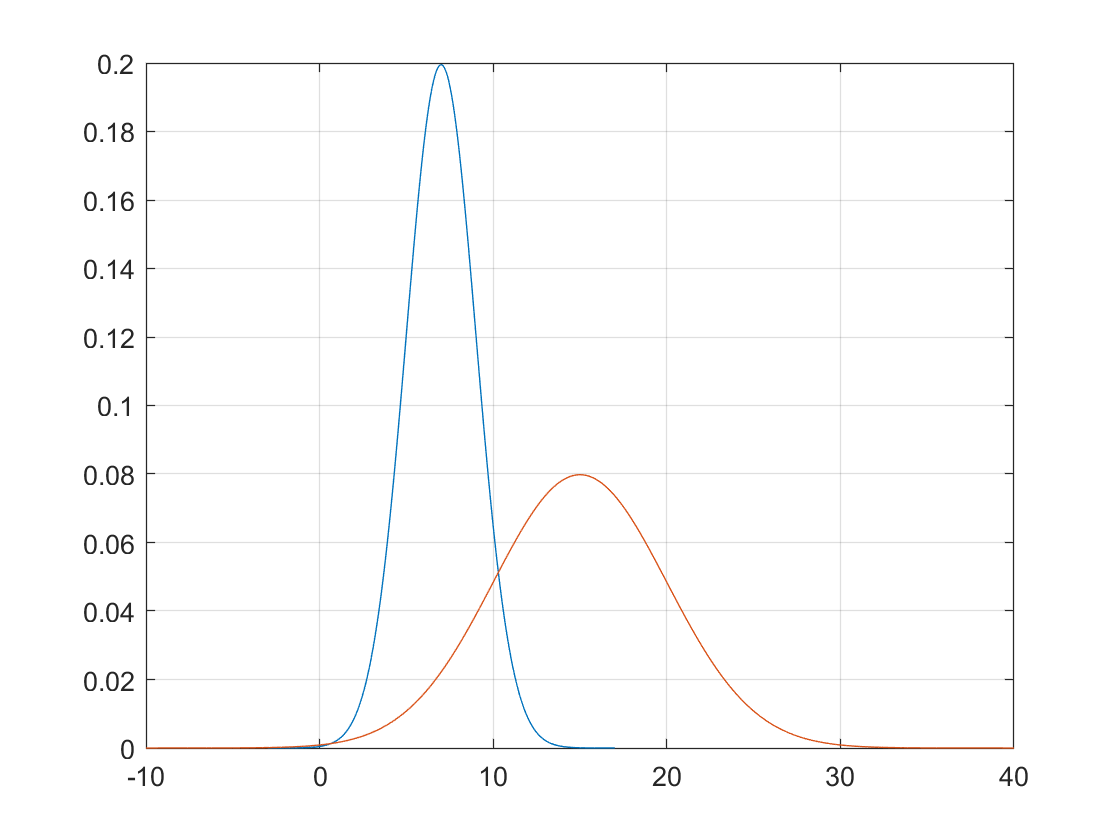

clc; clear all; close all;
rng('default')
mu1 = 7;                               %// Mean
sigma1 = 2;                            %// Standard deviation

mu2 = 15;                              %// Mean
sigma2 = 5;                            %// Standard deviation

%// Plot curve
x1 = (-5 * sigma1:0.01:5 * sigma1) + mu1;  %// Plotting range
y1 = exp(- 0.5 * ((x1 - mu1) / sigma1) .^ 2) / (sigma1 * sqrt(2 * pi));

x2 = (-5 * sigma2:0.01:5 * sigma2) + mu2;  %// Plotting range
y2 = exp(- 0.5 * ((x2 - mu2) / sigma2) .^ 2) / (sigma2 * sqrt(2 * pi));

plot(x1, y1)
grid on
hold on
plot(x2,y2)


dist1 =@(x) exp(-(x-mu1).^2 / (2*sigma1^2)) / sqrt(2*sigma1^2*pi);
dist2 =@(x) exp(-(x-mu2).^2 / (2*sigma2^2)) / sqrt(2*sigma2^2*pi);
fzero(@(x) dist1(x) - dist2(x), rand * (mu1 - mu2) + (mu1 + mu2)) % finds intersection between the two graphs

ans = 10.2969

## landmark-based with rotation

% i opgaven er der en rotation på 11 grader på det første ref punkt 
R=deg2rad(11);

rotation_matrice=[cos(R),-sin(R);sin(R),cos(R)];

D1_ref=[3;3];                       % X,Y cordinate of the reference landmark 
D1_ref=rotation_matrice*D1_ref;     % gør kun dette hvis det er givet der er en roation

D1_temp=[6;7];                      % X,Y cordinate of the template landmark

D2_ref=[4;2];
D2_temp=[3;7];

D3_ref=[7;3];
D3_temp=[2;2];

D1=sum(abs(D1_ref-D1_temp).^2);
D2=sum(abs(D2_ref-D2_temp).^2);
D3=sum(abs(D3_ref-D3_temp).^2);

D1+D2+D3

ans = 77.2882

## landmark-based with translation vector

translation_vector = [-2;5];

D1_ref=[1;6];                       % X,Y cordinate of the reference landmark 
D1_ref_trans=D1_ref+translation_vector;
D1_temp=[5;9];                      % X,Y cordinate of the template landmark

D2_ref=[8;8];
D2_ref_trans=D2_ref+translation_vector;
D2_temp=[4;3];

D3_ref=[3;2];
D3_ref_trans=D3_ref+translation_vector;
D3_temp=[6;5];

D1=sum(abs(D1_ref-D1_temp).^2);
D2=sum(abs(D2_ref-D2_temp).^2);
D3=sum(abs(D3_ref-D3_temp).^2);

sum1=D1+D2+D3;

D1_trans=sum(abs(D1_ref_trans-D1_temp).^2);
D2_trans=sum(abs(D2_ref_trans-D2_temp).^2);
D3_trans=sum(abs(D3_ref_trans-D3_temp).^2);

sum2=D1_trans+D2_trans+D3_trans;

svar=sum2-sum1

svar = 89

## template and registration, find missing cordinate

% vi getter dauda smidder alle værdier ind i et forloop og køre dem alle
% igennem se havd der giver det rigtig svar
clc; clear all; close all;
svar_muligheder =[4,3,-1,-2,7];
for i = svar_muligheder
    D1_ref=[3;-2];                    % X,Y cordinate of the reference landmark 
    D1_temp=[-1;5];                      % X,Y cordinate of the template landmark
    
    D2_ref=[i;2];
    D2_temp=[6;4];
    
    D1=sum(abs(D1_ref-D1_temp).^2);
    D2=sum(abs(D2_ref-D2_temp).^2);
    disp('svar mulighed: ')
    disp(i)
    sum1=D1+D2
end 

svar mulighed: 


     4



sum1 = 73

svar mulighed: 


     3



sum1 = 78

svar mulighed: 


    -1



sum1 = 118

svar mulighed: 


    -2



sum1 = 133

svar mulighed: 


     7



sum1 = 70

## Landmark optimal translation

clc; close all; clear all;

n=3                                 % antallet af punkter

n = 3


D1_ref=[4;0];                       % X,Y cordinate of the reference landmark 
D1_temp=[1;2];                      % X,Y cordinate of the template landmark

D2_ref=[2;5];
D2_temp=[3;-3];

D3_ref=[1;-1];
D3_temp=[4;1];

a=(1/n)*(D1_ref+D2_ref+D3_ref);
b=(1/n)*(D1_temp+D2_temp+D3_temp);

D1=sum(abs(D1_ref-D1_temp).^2);
D2=sum(abs(D2_ref-D2_temp).^2);
D3=sum(abs(D3_ref-D3_temp).^2);

t=b-a;

t =     0.3333
   -1.3333



F_without_translation=D1+D2+D3;

% now we apply the translation to all points 
D1_ref_with_trans=[4;0]+t;                       % X,Y cordinate of the reference landmark 

D2_ref_with_trans=[2;5]+t;

D3_ref_with_trans=[1;-1]+t;


D1_with_trans=sum(abs(D1_ref_with_trans-D1_temp).^2);
D2_with_trans=sum(abs(D2_ref_with_trans-D2_temp).^2);
D3_with_trans=sum(abs(D3_ref_with_trans-D3_temp).^2);


F_with_translation=D1_with_trans+D2_with_trans+D3_with_trans;

svar=F_without_translation-F_with_translation

svar = 5.6667

## accumulator image

%hvis accumulator image allerede er givet så ska du bare tage laveste
%værdier op til første row, hvis ikke er der en ligning på mongol PDF 760. 

% eksempel 

% eksamen sæt 2020 spørgsmål 25 husk at ligge værdien fra punktet vi
% starter i til. 

177+10+25+12+71

ans = 295

## decision boundary

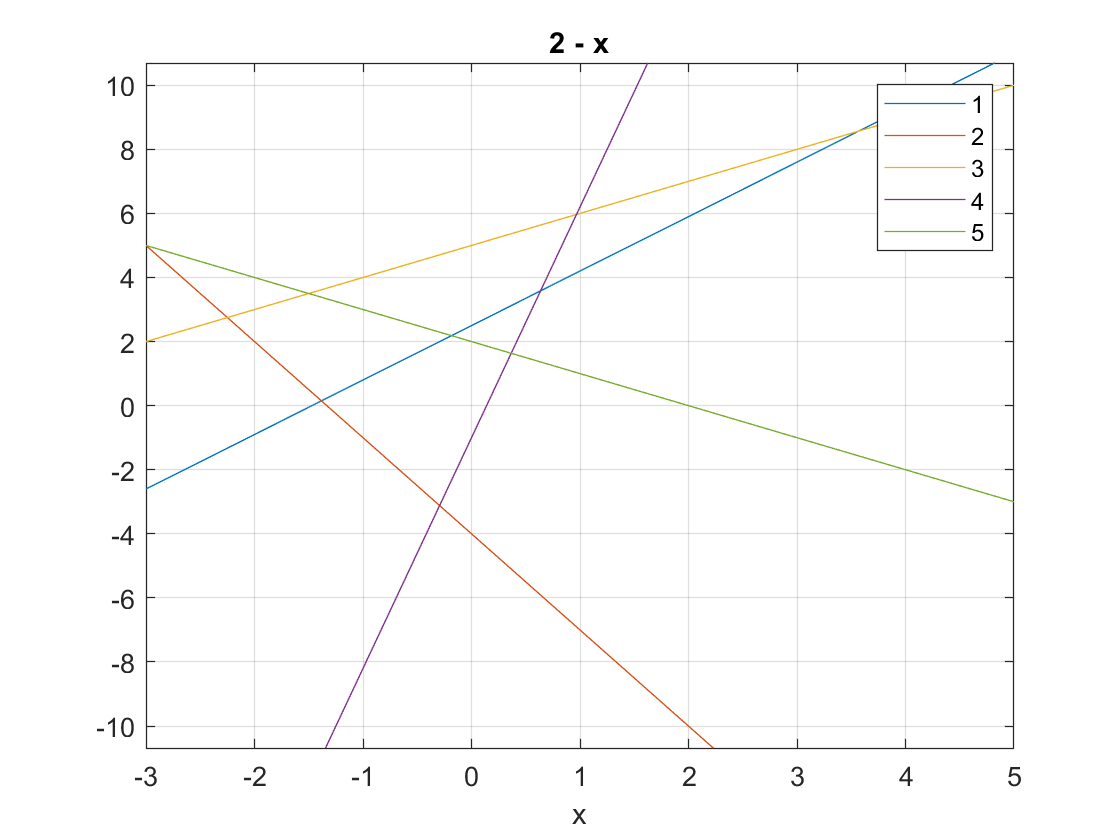

clc;clear all; close all;
syms x
y1=1.7*x+2.5;
y2=-3*x-4;
y3=x+5;
y4=7.2*x-1;
y5=-x+2;


ezplot(y1, [-3, 5])
hold on
ezplot(y2, [-3, 5])
hold on
ezplot(y3, [-3, 5])
hold on
ezplot(y4, [-3, 5])
hold on
ezplot(y5, [-3, 5])
legend('1','2','3','4','5')
grid on

xlim([-3.00 5.00])
ylim([-10.7 10.7])


% den eneste der giver mening er nummer 1 , de andre skær ind i data
% sættet.


## gamma mapping | dynamic programming

clc;clear all; close all;
gamma=1.12;
% tager alle værdier og mapper dem mellem 0-1. 
A =[246,244,36;
    40,23,108;
    55,200,234];

A_gamma=round(((A/255).^gamma)*255)

A_gamma =    245   243    28
    32    17    97
    46   194   232



%herfra skal bruges "daccumulator image" tjek side 760 i POWERPOINT
% men basicly tager du den A_gamma matrice og bygger videre på når du når
% til sidste linje skal du huske at du kigger på A_gamma hvilken
% ovenstående værdi er mindst men plusser med den værdi er er blevet sat
% ind efterfølgende 

B=[245,243,28;
    275,45,125;
    91,239,277]

B =    245   243    28
   275    45   125
    91   239   277


## transoformation matrix

clc; clear all; close all;
point = [5;4];
transformation_matrix1= [1.2,4.2;-1.2,2.1];


new_point=transformation_matrix1*point;

svar_muligheder = [0.4,1.2,-0.3,-2.1,4.1]

svar_muligheder =     0.4000    1.2000   -0.3000   -2.1000    4.1000



for i = svar_muligheder;
    X = sprintf('svarmulighed %d',i)
    [-0.6,1.1;i,1.2]*new_point
            
end

X = 'svarmulighed 4.000000e-01'

ans =   -11.0400
   12.0000


X = 'svarmulighed 1.200000e+00'

ans =   -11.0400
   30.2400


X = 'svarmulighed -3.000000e-01'

ans =   -11.0400
   -3.9600


X = 'svarmulighed -2.100000e+00'

ans =   -11.0400
  -45.0000


X = 'svarmulighed 4.100000e+00'

ans =   -11.0400
   96.3600


## principal component 

%example from 2020 page 11-12
average_image=[245,38,65;
                140,66,208;
                35,214,62]

average_image =    245    38    65
   140    66   208
    35   214    62



% selvom eigen-vectoren er lang, brug kun de første par værdier så den kan
% ligges sammen med billede størrelsen. 
w1=[93,35,19.5]*0.2;
w2=[54.9,91,28]*(-0.7);
w3=[53,77.9,93]*0.5;

round(((average_image+w1)+w2)+w3)

ans =    252    20    96
   147    48   239
    42   196    93


## bounding box

clc; clear all; close all;
%tæl længde og højde på matricen 
map=[[0 0 0 0 0 0 0 0]
    [0 0 0 0 0 0 0 0]
    [0 1 1 0 0 1 1 0]
    [0 0 0 1 0 0 0 0]
    [0 0 0 0 1 0 0 0]
    [0 0 0 0 1 0 0 0]
    [0 0 0 0 1 0 0 0]
    [0 0 0 0 0 0 0 0]]

map =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     1     1     0     0     1     1     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0


%største blob er 4 bred og 5 høj 
bound_box_ratio=4/5

bound_box_ratio = 0.8000

## Euclidean distance || Bounding Box

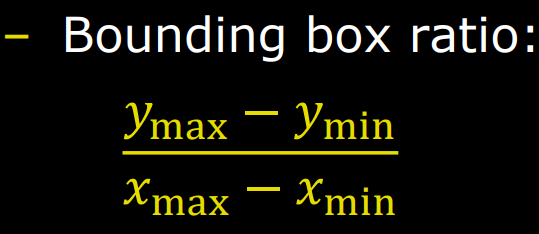

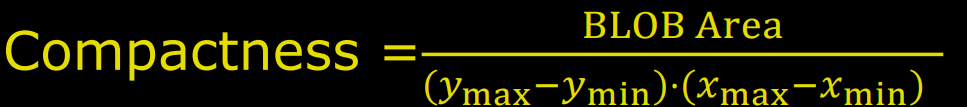

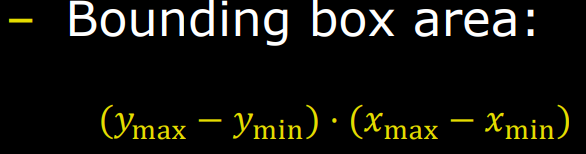

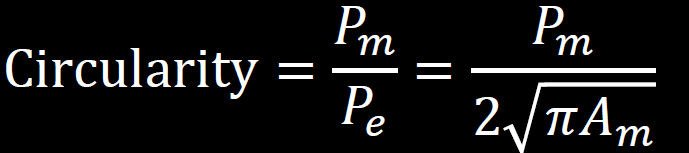

clc; clear all; close all; 
map_with_blob1=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,1,0,0,0,0,0,0,0,0,0,0;
                0,0,1,1,1,1,0,0,0,0,0,0,0,0,0;
                0,1,1,1,1,1,0,0,0,0,0,0,0,0,0;
                0,0,0,1,1,1,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
            
map_with_blob2=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,1,1,1,0,0,0,0,0,0,0,0,0,0;
                0,1,1,1,1,1,1,0,0,0,0,0,0,0,0;
                0,0,0,1,0,0,0,1,1,1,0,0,0,0,0;
                0,0,0,0,0,0,0,1,1,0,0,0,0,0,0;
                0,0,0,0,0,0,0,1,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
            
 
            
% determining the area of each blop by counting the number of occurances of
% 1 in the matrix
area_of_blob1=length(find(map_with_blob1==1));
area_of_blob2=length(find(map_with_blob2==1));

% estimating the perimeter of each blob
Pe_blob1=2*sqrt(pi*area_of_blob1);
Pe_blob2=2*sqrt(pi*area_of_blob2);

% measuring the perimeter of each blob
Pm_blob1=perim_calc(map_with_blob1);
Pm_blob2=perim_calc(map_with_blob2);

% calculating the circularity
circularity_blob1=Pm_blob1/(2*sqrt(pi*area_of_blob1));
circularity_blob2=Pm_blob1/(2*sqrt(pi*area_of_blob2));

% specifying the x,y values of each blob in feature space
cordinates_in_featurespace_blob1=[circularity_blob1,area_of_blob1];
cordinates_in_featurespace_blob2=[circularity_blob2,area_of_blob2];

% calculating the distance between the 2 points
%distance=sqrt((cordinates_in_featurespace_blob2(1)-cordinates_in_featurespace_blob1(1))^2+(cordinates_in_featurespace_blob2(2)-cordinates_in_featurespace_blob1(2))^2)

distance = 3.0032


reference_point=[]

% distance between 2 points and reference points
distanc1=sqrt((cordinates_in_featurespace_blob2(1)-cordinates_in_featurespace_blob1(1))^2+(cordinates_in_featurespace_blob2(2)-cordinates_in_featurespace_blob1(2))^2)
distanc2=sqrt((cordinates_in_featurespace_blob2(1)-cordinates_in_featurespace_blob1(1))^2+(cordinates_in_featurespace_blob2(2)-cordinates_in_featurespace_blob1(2))^2)



## Euclidean distance to reference point

clc; clear all; close all; 
map_with_blob1=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,1,0,0,0,0,0,0,0,0,0,0;
                0,0,1,1,1,1,0,0,0,0,0,0,0,0,0;
                0,1,1,1,1,1,0,0,0,0,0,0,0,0,0;
                0,0,0,1,1,1,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
            
map_with_blob2=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,1,1,1,0,0,0,0,0,0,0,0,0,0;
                0,1,1,1,1,1,1,0,0,0,0,0,0,0,0;
                0,0,0,1,0,0,0,1,1,1,0,0,0,0,0;
                0,0,0,0,0,0,0,1,1,0,0,0,0,0,0;
                0,0,0,0,0,0,0,1,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
            
map_with_blob3=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,1,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,1,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0]; 
            
map_with_blob4=[0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,1,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,1,1,1,0,0;
                0,0,0,0,0,0,0,0,0,0,1,1,1,0,0;
                0,0,0,0,0,0,0,0,0,1,1,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,1,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0;
                0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];        
            
% determining the area of each blop by counting the number of occurances of
% 1 in the matrix
area_of_blob1=length(find(map_with_blob1==1));
area_of_blob2=length(find(map_with_blob2==1));
area_of_blob3=length(find(map_with_blob3==1));
area_of_blob4=length(find(map_with_blob4==1));


bound_boxratio1=4/5;
bound_boxratio2=5/9;
bound_boxratio3=2/1;
bound_boxratio4=5/4;


% specifying the x,y values of each blob in feature space
cordinates_in_featurespace_blob1=[area_of_blob1,bound_boxratio1];
cordinates_in_featurespace_blob2=[area_of_blob2,bound_boxratio2];
cordinates_in_featurespace_blob3=[area_of_blob3,bound_boxratio3];
cordinates_in_featurespace_blob4=[area_of_blob4,bound_boxratio4];

% calculating the distance between the 2 points
%distance=sqrt((cordinates_in_featurespace_blob2(1)-cordinates_in_featurespace_blob1(1))^2+(cordinates_in_featurespace_blob2(2)-cordinates_in_featurespace_blob1(2))^2)

reference_point=[12,0.75];

% distance between 2 points and reference points
distanc1=sqrt((cordinates_in_featurespace_blob1(1)-reference_point(1))^2+(cordinates_in_featurespace_blob1(2)-reference_point(2))^2)
distanc2=sqrt((cordinates_in_featurespace_blob2(1)-reference_point(1))^2+(cordinates_in_featurespace_blob2(2)-reference_point(2))^2)
distanc3=sqrt((cordinates_in_featurespace_blob3(1)-reference_point(1))^2+(cordinates_in_featurespace_blob3(2)-reference_point(2))^2)
distanc4=sqrt((cordinates_in_featurespace_blob4(1)-reference_point(1))^2+(cordinates_in_featurespace_blob4(2)-reference_point(2))^2)

## specificity

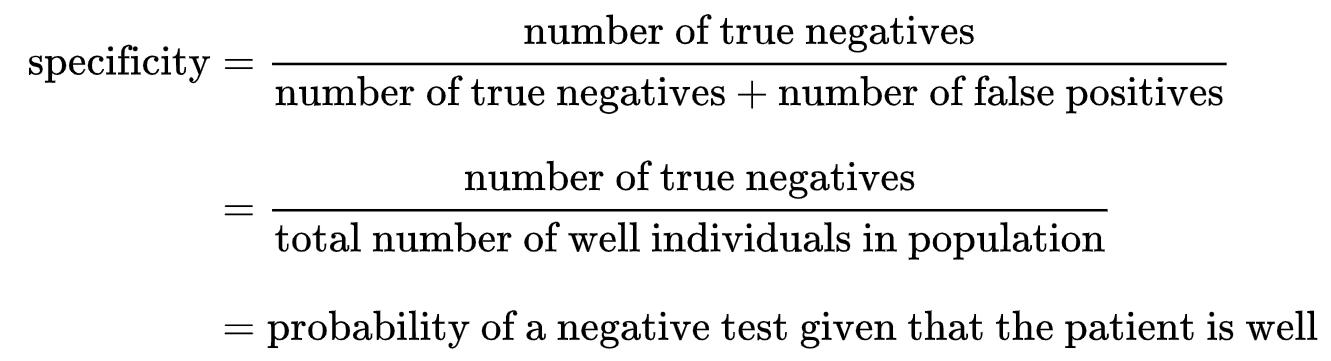

## functions

function Io = graylevelmapping(I,dmax,dmin)
% Stretches an image histogram to improve contrast
Itemp = double(I);

% Stretch the image intensities to span the entire
% spectrum:
vmax_d = dmax;
vmin_d = dmin;

% Get vmax and vmin
vmin = min(Itemp(:));
vmax = max(Itemp(:));

Itemp = ((vmax_d - vmin_d) / (vmax - vmin)) * (Itemp - vmin) + vmin_d;
Io = uint8(Itemp);
end

function perim = perim_calc(map)
% Get complement of image, with a border round it in case the
% blob is at the boundary
notimg = true(size(map)+2);
notimg(2:end-1, 2:end-1) = ~map;
% Find locations where a non-zero pixel is adjacent to a zero pixel,
% for each cardinal direction in turn
topedges =    map & notimg(1:end-2, 2:end-1);
leftedges =   map & notimg(2:end-1, 1:end-2);
bottomedges = map & notimg(3:end,   2:end-1);
rightedges =  map & notimg(2:end-1, 3:end);
% Sum each set of locations separately, then add to get total perimeter
perim = sum(topedges(:)) + sum(leftedges(:)) + ...
    + sum(bottomedges(:)) + sum(rightedges(:));
end